# 02686 - Scientific Computing for Differential Equations - Exam 

## 6 - Dormand-Prince 5

## Dormand-Prince 5

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 10000;
t0 = 0; tf = 50;

[T,X] = dopri54FixedStepSize(@VanDerPol,0,tf,N,x0,mu);
[T1,X1] = dopri54FixedStepSize(@VanDerPol,0,tf,N,x0,mu2);

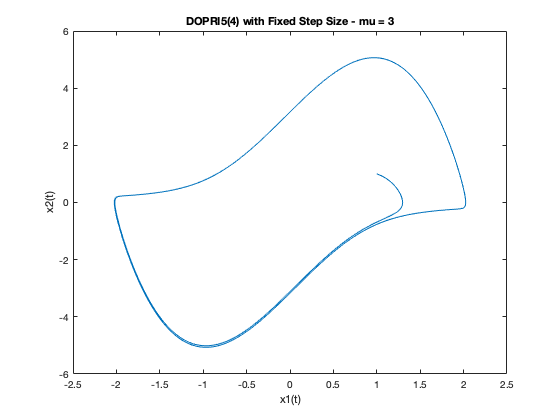

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Fixed Step Size - mu = 3')

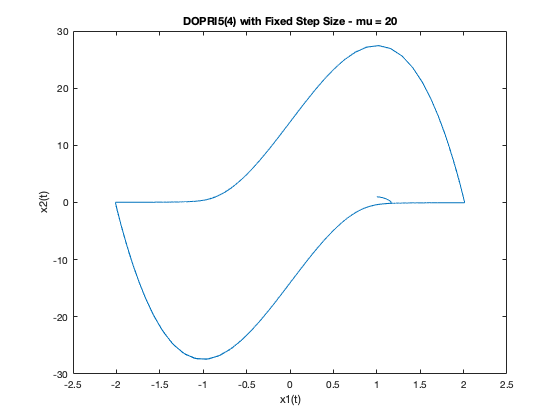


plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Fixed Step Size - mu = 20')

## For test equation

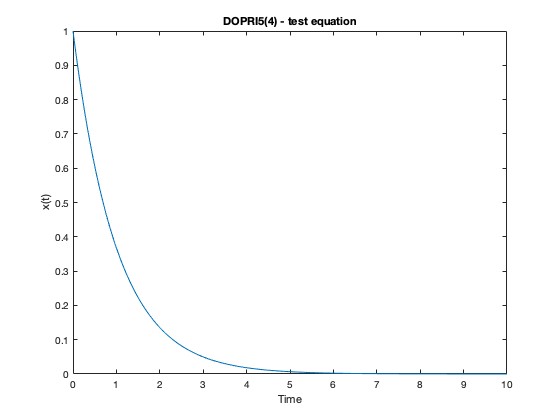

x0 = 1.0;
abstol = 1e-7;
reltol = 1e-7;
N = 5000;

T_final = 10;
[T,X,info] = dopri54AdaptativeStepSize(@testEquation,t0,T_final,x0,N,abstol,reltol);

plot(T,X)
xlabel('Time')
ylabel('x(t)')
title('DOPRI5(4) - test equation')

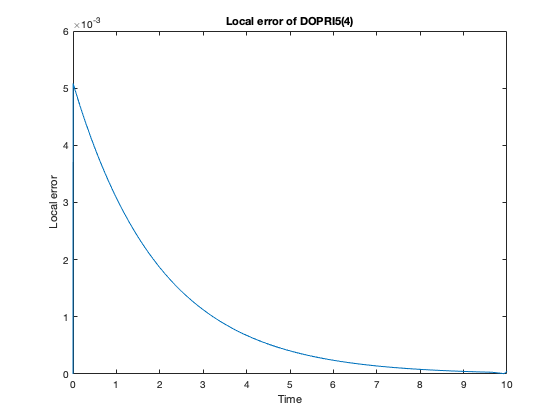

% Local and global truncation errors
l = local_error(T,X);
plot(T,l);
title("Local error of DOPRI5(4)");
xlabel("Time");
ylabel("Local error");

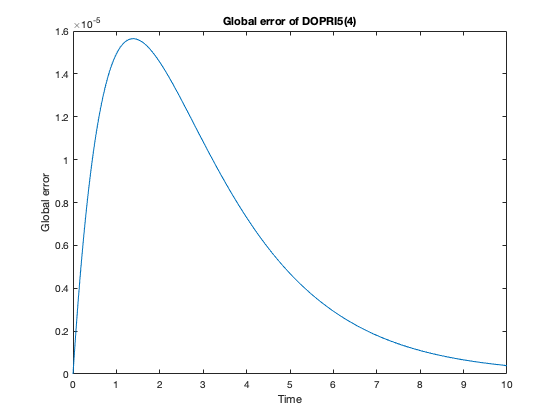

g = global_error(T,X);
plot(T,g);
title("Global error of DOPRI5(4)");
xlabel("Time");
ylabel("Global error");

## DOPRI5(4) with Adaptative Step Size

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 15000;
t0 = 0; tf = 50;

abstol = 1e-7;
reltol = 1e-7;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
[T1,X1,info1] = dopri54AdaptativeStepSize(@VanDerPol,0,tf,x0,N,abstol,reltol,mu2);

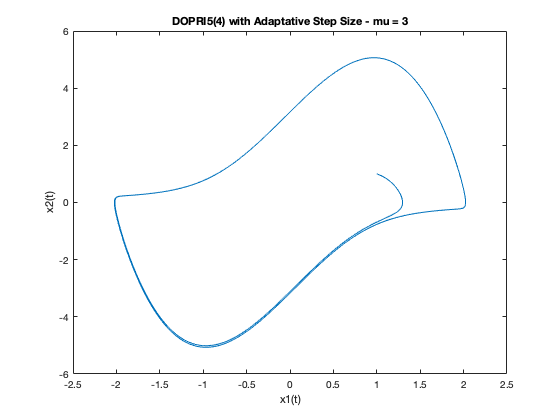

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Adaptative Step Size - mu = 3')

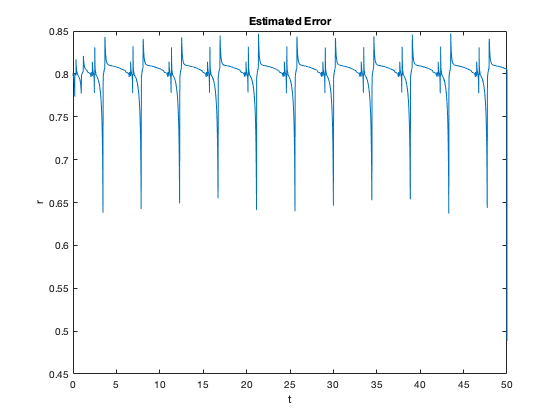


n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

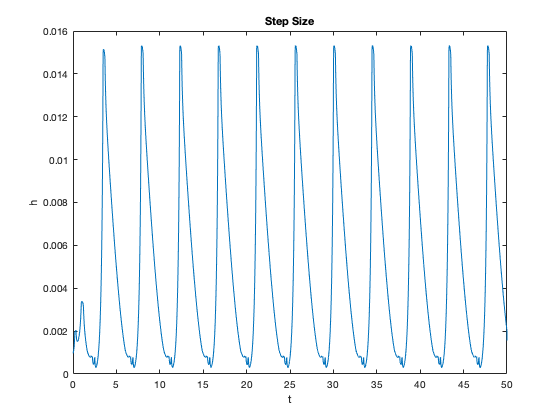


plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")
title("Step Size")

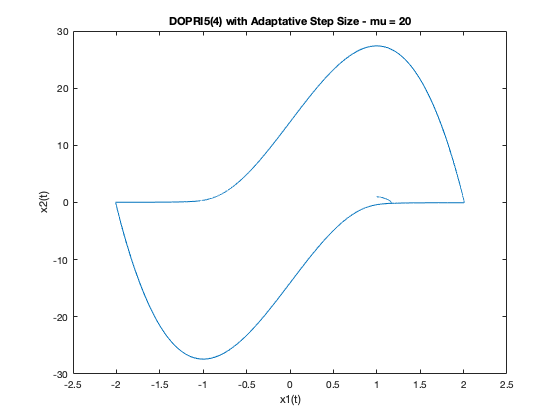

plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Adaptative Step Size - mu = 20')

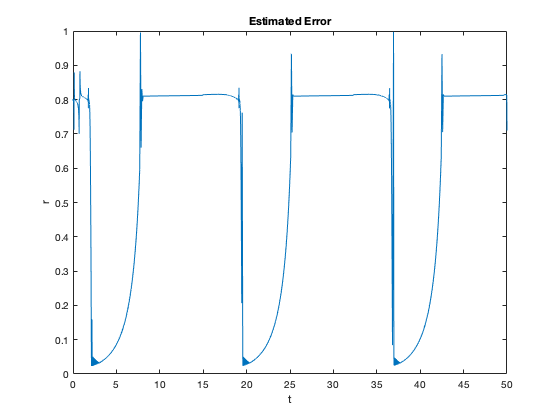


n = length(T1);

plot(T1(2:n),info1.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

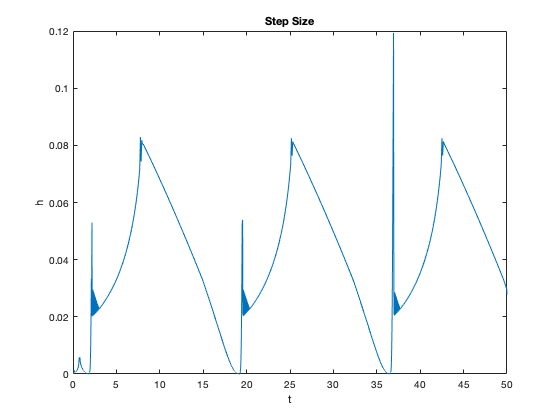


plot(T1(2:n),info1.hh)
xlabel("t")
ylabel("h")
title("Step Size")

## Stability Plot

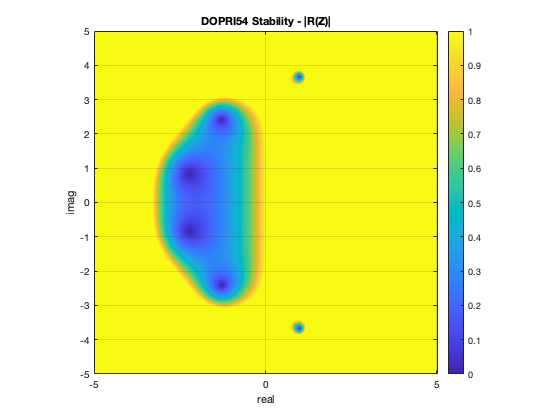

% Stability plot

alpha = -5:0.01:5;
beta = -5:0.01:5;

nreal = length(alpha);
nimag = length(beta);

absR = zeros(nreal,nimag);
absR2 = zeros(nreal,nimag);
absR3 = zeros(nreal,nimag);

% For classical Runge Kutta :
A = zeros(7,7);
A(2,1) = 1/5;
A(3,1) = 3/40;
A(4,1) = 44/45;
A(5,1) = 19372/6561;
A(6,1) = 9017/3168;
A(7,1) = 35/384;
A(3,2) = 9/40;
A(4,2) = -56/15;
A(5,2) = -25360/2187;
A(6,2) = -355/33;
A(4,3) = 32/9;
A(5,3) = 64448/6561;
A(6,3) = 46732/5247;
A(7,3) = 500/1113;
A(5,4) = -212/729;
A(6,4) = 49/176;
A(7,4) = 125/192;
A(6,5) = -5103/18656;
A(7,5) = -2187/6784;
A(7,6) = 11/84;
b = [35/384; 0; 500/1113; 125/192; -2187/6784; 11/84; 0];
I = eye(size(A));
e = ones(size(A,1),1);

for kreal = 1:nreal 
    for kimag = 1:nimag 
        z = alpha(kreal)+i*beta(kimag);
        tmp = (I-z*A)\e;
        R = 1 + z*b'*tmp;
        absR(kimag,kreal) = abs(R);
    end
end

imagesc(alpha,beta,absR,[0,1]);
colorbar
grid on
axis image
axis xy
xlabel('real');
ylabel('imag');
title('DOPRI54 Stability - |R(Z)|');

## Solver ODE45,ODE15,DOPRI5(4)

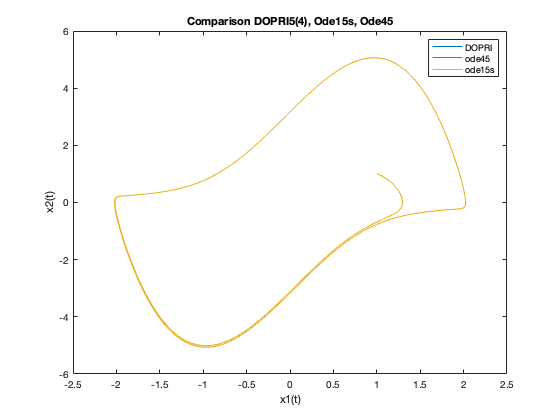

mu = 3;
x0 = [1.0; 1.0];
t0 = 0; tf = 50;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,t0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X2(:,1),X2(:,2))
hold on 
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X3(:,1),X3(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Comparison DOPRI5(4), Ode15s, Ode45')
legend('DOPRI','ode45','ode15s')

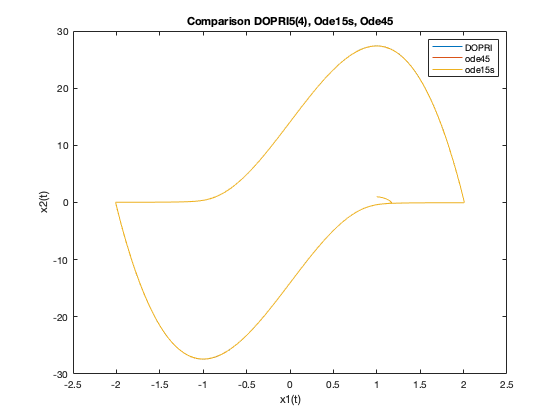

mu = 20;
x0 = [1.0; 1.0];
t0 = 0; tf = 50;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,t0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X2(:,1),X2(:,2))
hold on 
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X3(:,1),X3(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Comparison DOPRI5(4), Ode15s, Ode45')
legend('DOPRI','ode45','ode15s')

# CSTR problem

## 1-Dimensional

abstol = 1e-7;
reltol = 1e-7;

% Parameters
rho = 1.0;      % density
cp = 4.186;      % specific heat capacity
k0 = 4.8266*(10^10); % Arrhenius constant
EaR = 8500;     % Activation Energy
delHr = -560;   % Reaction enthalpy
V = 1.0;      % Reactor Volume
CAin = 0.8;   % Inlet Concentration of A
CBin = 1.6;   % Inlet Concentration of B
Tin = 273.65;       % Inlet Temperature

p = [rho; cp; k0; EaR; delHr; V; CAin; CBin; Tin];

x0 = 0; % Initial Temperature
t0 = 0; 
T_final = 35; 

u = 0.5; % Flow Rate
[T,X1,info] = dopri54AdaptativeStepSizeCSTR(@CSTR1d,0,T_final,u,x0,abstol,reltol,p);
u = 0.2; % Flow Rate
[T,X2,info] = dopri54AdaptativeStepSizeCSTR(@CSTR1d,0,T_final,u,x0,abstol,reltol,p);
u = 0.7; % Flow Rate
[T,X3,info] = dopri54AdaptativeStepSizeCSTR(@CSTR1d,0,T_final,u,x0,abstol,reltol,p);

beta = -delHr/(rho*cp);
% X1 is a List of temperature 
% We compute the extent of reaction B = (X)
X1_true = -(2*(x0-X1))/(beta*CBin);

plot(T,X1)
hold on 
plot(T,X2)
hold on 
plot(T,X3)
hold off 
xlabel('time')
ylabel('Temperature')
title('CSTR Problem - 1D-version - Temperature over time')
legend('u=0.5','u=0.2','u=0.7')

## 3D Dimensional

% Parameters
rho = 1.0;      % density
cp = 4.186;      % specific heat capacity
k0 = 4.8266*(10^10); % Arrhenius constant
EaR = 8500;     % Activation Energy
delHr = -560;   % Reaction enthalpy
V = 0.1;      % Reactor Volume
CAin = 0.8;   % Inlet Concentration of A
CBin = 1.2;   % Inlet Concentration of B
Tin = 273.65;       % Inlet Temperature

p = [rho; cp; k0; EaR; delHr; V; CAin; CBin; Tin];
x0 = [1 1 1];
N = 10000;
T_final = 35;
u = 0.5;
[T,X1,info] = dopri54AdaptativeStepSizeCSTR(@CSTR3d,0,T_final,u,x0,abstol,reltol,p);
u = 0.2; % Flow Rate
[T,X2,info] = dopri54AdaptativeStepSizeCSTR(@CSTR3d,0,T_final,u,x0,abstol,reltol,p);
u = 0.7; % Flow Rate
[T,X3,info] = dopri54AdaptativeStepSizeCSTR(@CSTR3d,0,T_final,u,x0,abstol,reltol,p);

plot(T,X1)
hold on 
plot(T,X2)
hold on 
plot(T,X3)
hold off 
xlabel('time')
ylabel('Temperature')
title('CSTR Problem - 3D-version - Temperature over time')
legend('u=0.5','u=0.2','u=0.7')